# Exercise 1

Part 1: SISO System

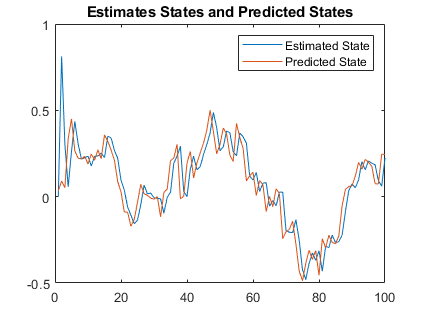

clf;
%Initialize 
A = [1 1; 0 1];
B = [0; 1];
C = [1 0];
D = 0;

L = [];
P = [];
x_hat = [];
x_bar = [];
p_bar = [];
x = [];
y = [];
mean_sqr_err = [];

N = 100;
x(:, 1) = rand(2,1);
x_bar(:, 1) = [0; 0];
v = 0.01;
w_k = [0 0; 0 0.1];
p_bar(:,:,1) = w_k; 
L(:, 1) = [0; 0];
s = [1 0; 0 1];
u = 0;

for i = 1:100
    %Estimation
    noise_a = 0.01 * randn;
    y(i) = C * x(:, i) + noise_a; 
    x_hat(:, i) = x_bar(:, i) + L(:, i) * (y(i) - C * x_bar(:, i));
    P(:, :, i) = (s - L(:, i) * C) * p_bar(:, :, i);
    x_bar(:, i + 1) = A * x_hat(:, i) + B * u;
    %Prediction Kalman Intro Notes pg 8
    p_bar(:, :, i + 1) = A * P(:, :, i) * transpose(A) + w_k;
    L(:, i + 1) = p_bar(:, :, i + 1) * transpose(C)  * inv(C * p_bar(:, :, i + 1) * transpose(C) + v) ;
    noise_b = [0; 1] * 0.1 * randn(1);
    x(:, i + 1) = A * x(:, i) + noise_b;  
end
figure(1)
plot(1:N, x_hat(2, 1:N))
hold on;
plot(1:N, x(2, 1:N))
hold off;
legend('Estimated State', 'Predicted State')
title('Estimates States and Predicted States')

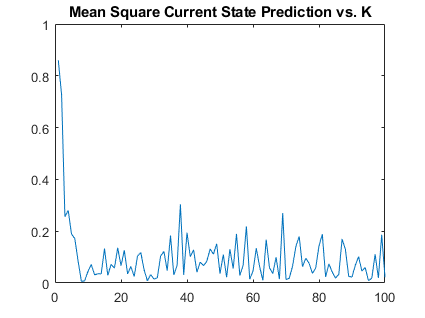

%Error Plot
for i = 1:N
    val_one = x_hat(1,i) - x(1,i);
    val_two = x_hat(2,i) - x(2,i);
    mean_sqr_err(i) = sqrt(val_one^2 + val_two^2);
end
figure(2)
plot(1:N, mean_sqr_err)
title('Mean Square Current State Prediction vs. K')

Part 2: Double Integrator

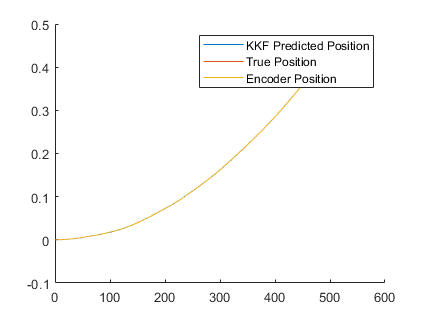

clf;
T = 0.002;

A = [1 T; 0 1];
B = [T^2 / 2; T];
C = [1 0];
D = 0;

accel_noise = 2.5;
encoder_noise = 2e-4;
end_T = 1;
time = 0:0.002:1;

L = [];
P = [];
x_hat = [];
x_bar = [];
p_bar = [];
x = [];
y = [];

w_k = [(T^2 / 2) * accel_noise 0; 0 T * accel_noise];
v_k = (encoder_noise^2) / 12;
x(:, 1) = [0; 0];
x_bar(:, 1) = [0; 0];
p_bar(:,:,1) = w_k; 
L(:, 1) = [0; 0];
s = [1 0; 0 1];
u = 0.1;
N = 501;

for i = 1:N
    %Estimation
    noise_a = encoder_noise * randn;
    noise_b = accel_noise * randn + 1;
    y(i) = C * x(:, i) + noise_a; 
    x_hat(:, i) = x_bar(:, i) + L(:, i) * (y(i) - C * x_bar(:, i));
    P(:, :, i) = (s - L(:, i) * C) * p_bar(:, :, i);
    x_bar(:, i + 1) = A * x_hat(:, i) + B * u;
    p_bar(:, :, i + 1) = A * P(:, :, i) * transpose(A) + w_k;
    L(:, i + 1) = p_bar(:, :, i + 1) * transpose(C)  * inv(C * p_bar(:, :, i + 1) * transpose(C) + v_k) ;
    x(:, i + 1) = A * x(:, i) + B * noise_b;  
end
figure(3)
hold on;
plot(1:N,x(1,1:end-1))
plot(1:N,x_hat(1,:))
plot(1:N,y)
legend('KKF Predicted Position', 'True Position', 'Encoder Position')